function pixel = lagrng(x, y, n, xx)
    sum = 0;

    for i = 1: n
        product = double(y(i));
        for j = 1: n
            if i ~= j
                fg = x(j);
                gf = x(i);
                h = double(xx) - x(j);
                g = x(i) - x(j);
                hola = h/double(g);
                product = product*hola;
            end
        end
        sum = sum + product;
    end
    pixel = sum;
end

function canalImage = repairCanalImage(image, row, col)
    for i = 2:row-1
        for j = 2:col-1
            if image(i, j) == 0 || image(i, j) == 255
                indexes = [];
                pixels = [];
                nearPixels = image(i-1:i+1, j-1:j+1);
                arrPixels = reshape(nearPixels, [1, 9]);
                [n, m] = size(arrPixels);
                for k = 1:m
                    if arrPixels(k) ~= 0 || arrPixels(k) ~= 255
                        indexes = [indexes k];
                        pixels = [pixels arrPixels(k)];
                    end
                end
                if length(indexes) >= 2
                    valorReparado = lagrng(indexes, pixels, length(indexes), 1);
                    image(i, j) = clip(valorReparado, 0, 255);
                end
            end
        end
        canalImage = image;
    end
end

function newImage = prepareImage(url_image)
    image = imread(url_image);

    imshow(image);

    im_r = image(:,:,1);
    im_g = image(:,:,2);
    im_b = image(:,:,3);

    [row_r, col_r] = size(im_r);
    [row_g, col_g] = size(im_g);
    [row_b, col_b] = size(im_b);

    new_img_r = repairCanalImage(im_r, row_r, col_r);
    new_img_g = repairCanalImage(im_r, row_g, col_g);
    new_img_b = repairCanalImage(im_b, row_b, col_b);

    image(:,:,1) = new_img_r;
    image(:,:,2) = new_img_g;
    image(:,:,3) = new_img_b;

    newImage = image;
end

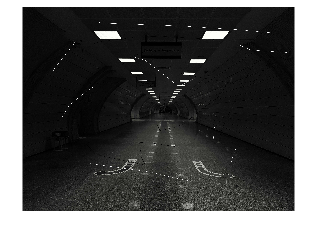

newImage = prepareImage('Images\gris_2_alt.jpg');

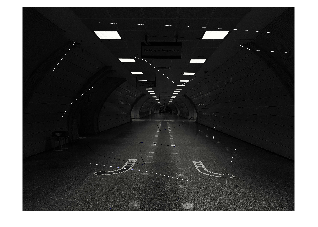

imshow(newImage)

imwrite(newImage, "Images/newImage1.jpg")

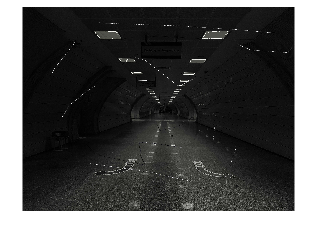

for i = 1:200
    newNewImage = prepareImage(sprintf('Images/newImage%d.jpg', i));
    imwrite(newNewImage, sprintf('Images/newImage%d.jpg', i+1));
end

[m, n, p] = size(image);
m = [1 2 3; 2 3 4]

m =      1     2     3
     2     3     4


size(m)

ans =      2     3


m(1:2, 1:2) = [34 32; 34 56]

m =     34    32     3
    34    56     4
